r_W =    1.000000000000000
   0.750255332855114
   0.558720716063972
   0.411828654316954
   0.299173933573923
   0.212776529219576
   0.146517205505455
   0.095698174782212
   0.056700032457810
   0.027343765652879


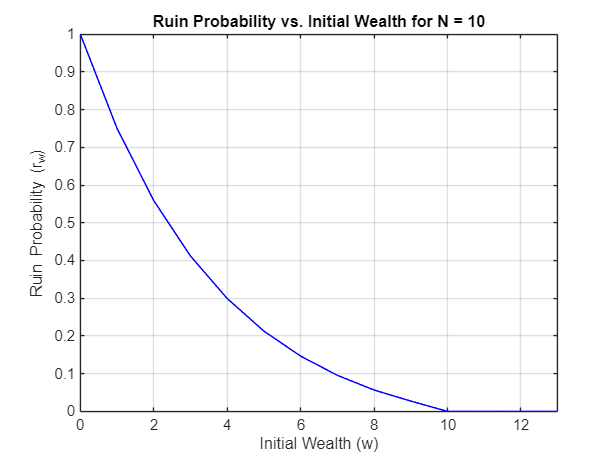

r_W =    1.000000000000000
   0.766921366027059
   0.588168292668190
   0.451078673209760
   0.345941662639168
   0.265309802726007
   0.203471475786985
   0.156046318005238
   0.119674933106009
   0.091780927026454


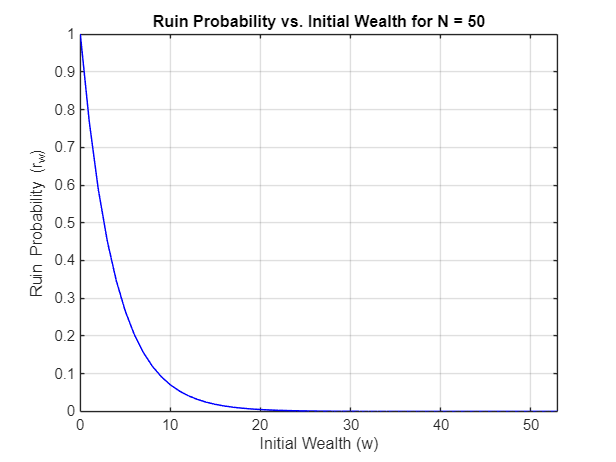

r_W =    1.000000000000000
   0.766921747874441
   0.588168967362634
   0.451079572494985
   0.345942734167948
   0.265311006352114
   0.203472780721406
   0.156047700635208
   0.119676375322384
   0.091782414940940


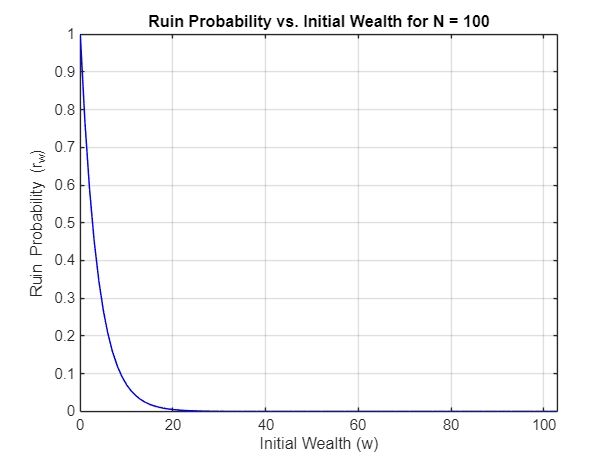

format long

N_values = [10, 50, 100]; 
n = length(N_values);
p_1 = 125/324;
p_2 = 25/216;
p_3 = 5/324;
p_4 = 1/1296;
q = 625/1296;

%S_0 = zeros(1, N+2);
%S_0(w+1) = 1; % Set w-th column

%disp(S_0);

for i = 1:n
    N = N_values(i);

P = zeros(N+4, N+4);  

P(1,1) = 1;
P(N+1,N+1) = 1;
P(N+2,N+2) = 1; 
P(N+3,N+3) = 1; 
P(N+4,N+4) = 1; 


for row = 2:N
    P(row, row-1) = q; 
    P(row, row) = 0;
    P(row, row+1) = p_1;
    P(row, row+2) = p_2;
    P(row, row+3) = p_3;
    P(row, row+4) = p_4;
end

P;
Q = P(2:N, 2:N); %transient to transient 
R = [P(2:N, 1), P(2:N, N+1), P(2:N, N+2), P(2:N, N+3), P(2:N, N+4)]; %transient to absorption
I = eye(size(Q));
F = inv(I-Q);
H = F*R;
H_full = [P(1,1), P(1,N+1), P(1,N+2), P(1,N+3), P(1,N+4); H; P(N+1,1), P(N+1,N+1), P(N+1,N+2), P(N+1,N+3), P(N+1,N+4); P(N+2,1), P(N+2,N+1), P(N+2,N+2), P(N+2,N+3), P(N+2,N+4); P(N+3,1), P(N+3,N+1), P(N+3,N+2), P(N+3,N+3), P(N+3,N+4); P(N+4,1), P(N+4,N+1), P(N+4,N+2), P(N+4,N+3), P(N+4,N+4)];
r_W = H_full(:,1)
figure;
plot(0:N+3, r_W, 'b', 'LineWidth', 1);
xlabel('Initial Wealth (w)');
ylabel('Ruin Probability (r_w)');
title(['Ruin Probability vs. Initial Wealth for N = ', num2str(N)]);
grid on;
xlim([0 N+3])
ylim([0.000 1.000])

end